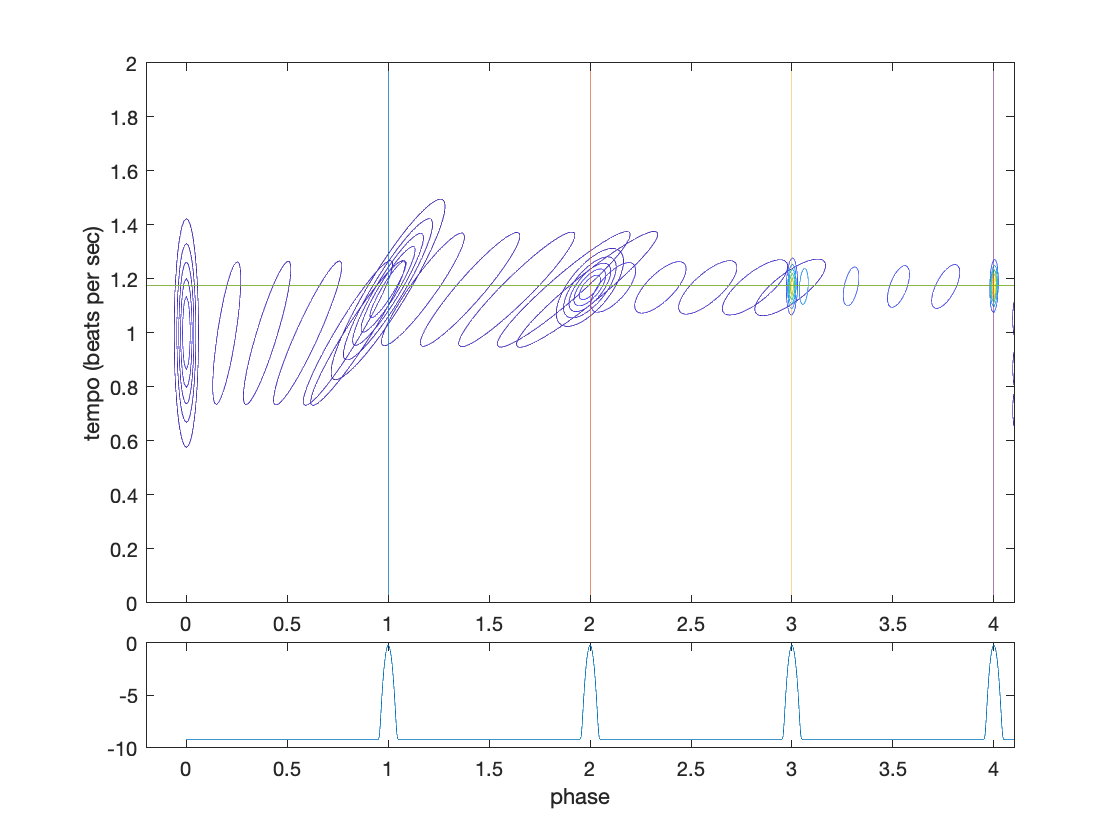

params = PATIPPET_params(...
    'events_unit', [1],...
    'expected_cycles', 4,...
    'expected_period', 1,...
    'true_speed', 1/.85,...
    'event_times', .85:.85:3.6,...%[.8, 1.6, 2.4, 3.2, 4.0],...
    'sigma_2', 0.05,...
    'C_0', [.001,0; 0,.05],...
    'mu_0', [0, 1],...
    'lambda_0', .0001,...
    'title', 'Not too syncopated');
[mu_list, C_list] = run_PATIPPET(params);


wrap = false;


t_max = 3;
dt = 0.01;
t_list = 0:dt:t_max;


e_means = [1, 2, 3]%, 4, 5];

e_means =      1     2     3


e_vars = [1, 1, 1]*.002%, 1, 1]*.001;

e_vars =     0.0020    0.0020    0.0020


e_lambdas = 30*[1, 1, 1]*.1%, 1, 1]*.1;

e_lambdas =      3     3     3


lambda_0 = .001;

interval = 1

interval = 1

event_times = []%[.8, 1.6, 2.4]%2.8, 3.6, 4.4];


event_times =

     []




template = zeros(length(t_list));
for i = 1:length(e_means)
    template = template + e_lambdas(i)*gauss_distribution(t_list, e_means(i), e_vars(i))';
end
template = template + lambda_0;

if wrap
    e_means = [e_means - 1, e_means, e_means+1];
    e_vars = [e_vars, e_vars, e_vars];
    e_lambdas = [e_lambdas, e_lambdas, e_lambdas];
end

mu_s = @(mu, C) mu_star(mu, C, lambda_0, e_lambdas, e_means, e_vars)

mu_s = function_handle with value:
    @(mu,C)mu_star(mu,C,lambda_0,e_lambdas,e_means,e_vars)


C_s = @(mu, C) C_star(mu, C, lambda_0, e_lambdas, e_means, e_vars)

C_s = function_handle with value:
    @(mu,C)C_star(mu,C,lambda_0,e_lambdas,e_means,e_vars)


Lambda_s = @(mu, C) Lambda_star(mu, C, lambda_0, e_lambdas, e_means, e_vars)

Lambda_s = function_handle with value:
    @(mu,C)Lambda_star(mu,C,lambda_0,e_lambdas,e_means,e_vars)




mu_list = zeros(2, length(t_list));
mu_list(:,1) = [0, 1];

C_list = zeros(2,2,length(t_list));
C_list(:,:,1) = [.0001,0; 0,.04];

sigma = .1;
sigma_T = .02;

for i=2:length(t_list)
    t = t_list(i);
    t_past = t_list(i-1);
    C_past = C_list(:,:,i-1);
    mu_past = mu_list(:,i-1);
    dmu = [mu_past(2); 0]*dt...
        - Lambda_s(mu_past, C_past)*(mu_s(mu_past, C_past)-mu_past)*dt;
    dC = [sigma^2 + 2*C_past(1,2), C_past(2,2); C_past(2,2), sigma_T^2]*dt...
        - Lambda_s(mu_past, C_past)*(C_s(mu_past, C_past)-C_past)*dt;
    mu = mu_past+dmu;
    C = C_past+dC;
    
    for j = 1:length(event_times)
        if t>=event_times(j) & t_past<event_times(j)
            i
            mu = mu_s(mu, C);
            C = C_s(mu, C);
        end
    end
    
    mu_list(:,i) = mu;
    C_list(:,:,i) = C;
end

Li = 1.0315e-102

extra =     0.0023         0
         0         0


Li = 0

extra =     0.0091         0
         0         0


Li = 0

extra =     0.0204         0
         0         0


ans = 'ding'

Li = 4.6529e-96

extra =     0.0081    0.0162
    0.0162    0.0324


Li = 0

extra =     0.0327    0.0655
    0.0655    0.1309


Li = 0

extra =     0.0739    0.1478
    0.1478    0.2955


ans = 'ding'

Li = 1.0904e-89

extra =     0.0171    0.0444
    0.0444    0.1154


Li = 0

extra =     0.0698    0.1814
    0.1814    0.4711


Li = 0

extra =     0.1581    0.4108
    0.4108    1.0670


ans = 'ding'

Li = 1.2529e-83

extra =     0.0288    0.0815
    0.0815    0.2306


Li = 0

extra =     0.1187    0.3361
    0.3361    0.9513


Li = 0

extra =     0.2699    0.7639
    0.7639    2.1622


ans = 'ding'

Li = 6.8212e-78

extra =     0.0426    0.1245
    0.1245    0.3635


Li = 0

extra =     0.1777    0.5189
    0.5189    1.5152


Li = 0

extra =     0.4053    1.1835
    1.1835    3.4558


ans = 'ding'

Li = 1.7340e-72

extra =     0.0581    0.1709
    0.1709    0.5028


Li = 1.8492e-307

extra =     0.2448    0.7202
    0.7202    2.1185


Li = 0

extra =     0.5603    1.6482
    1.6482    4.8485


ans = 'ding'

Li = 2.0598e-67

extra =     0.0747    0.2187
    0.2187    0.6403


Li = 3.5293e-289

extra =     0.3182    0.9316
    0.9316    2.7273


Li = 0

extra =     0.7309    2.1396
    2.1396    6.2637


ans = 'ding'

Li = 1.1584e-62

extra =     0.0920    0.2662
    0.2662    0.7702


Li = 6.6098e-272

extra =     0.3962    1.1464
    1.1464    3.3171


Li = 0

extra =     0.9132    2.6423
    2.6423    7.6450


ans = 'ding'

Li = 3.1535e-58

extra =     0.1096    0.3121
    0.3121    0.8887


Li = 1.2446e-255

extra =     0.4772    1.3591
    1.3591    3.8705


Li = 0

extra =     1.1038    3.1435
    3.1435    8.9523


ans = 'ding'

Li = 4.2757e-54

extra =     0.1271    0.3553
    0.3553    0.9935


Li = 2.4854e-240

extra =     0.5598    1.5653
    1.5653    4.3766


Li = 0

extra =     1.2995    3.6335
    3.6335   10.1591


ans = 'ding'

Li = 2.9844e-50

extra =     0.1442    0.3953
    0.3953    1.0835


Li = 5.6707e-226

extra =     0.6428    1.7618
    1.7618    4.8288


Li = 0

extra =     1.4976    4.1045
    4.1045   11.2494


ans = 'ding'

Li = 1.1112e-46

extra =     0.1608    0.4316
    0.4316    1.1585


Li = 1.6166e-212

extra =     0.7252    1.9464
    1.9464    5.2243


Li = 0

extra =     1.6956    4.5510
    4.5510   12.2152


ans = 'ding'

Li = 2.2904e-43

extra =     0.1766    0.4640
    0.4640    1.2188


Li = 6.3573e-200

extra =     0.8061    2.1175
    2.1175    5.5628


Li = 0

extra =     1.8916    4.9693
    4.9693   13.0545


ans = 'ding'

Li = 2.7126e-40

extra =     0.1915    0.4923
    0.4923    1.2653


Li = 3.8291e-188

extra =     0.8848    2.2743
    2.2743    5.8458


Li = 0

extra =     2.0841    5.3570
    5.3570   13.7698


ans = 'ding'

Li = 1.9152e-37

extra =     0.2054    0.5165
    0.5165    1.2990


Li = 3.9305e-177

extra =     0.9608    2.4162
    2.4162    6.0763


Li = 0

extra =     2.2717    5.7127
    5.7127   14.3662


ans = 'ding'

Li = 8.3538e-35

extra =     0.2182    0.5369
    0.5369    1.3210


Li = 7.6509e-167

extra =     1.0338    2.5434
    2.5434    6.2577


Li = 0

extra = 2×2
    2.4534    6.0362
    6.0362   14.8512


ans = 'ding'

Li = 2.3299e-32

extra = 2×2
    0.2299    0.5536
    0.5536    1.3326


Li = 3.1361e-157

extra = 2×2
    1.1033    2.6561
    2.6561    6.3943


Li = 0

extra = 2×2
    2.6284    6.3276
    6.3276   15.2332


ans = 'ding'

Li = 4.2931e-30

extra = 2×2
    0.2405    0.5667
    0.5667    1.3351


Li = 2.9964e-148

extra = 2×2
    1.1692    2.7547
    2.7547    6.4902


Li = 0

extra = 2×2
    2.7962    6.5879
    6.5879   15.5212


ans = 'ding'

Li = 5.3895e-28

extra = 2×2
    0.2500    0.5765
    0.5765    1.3295


Li = 7.3563e-140

extra = 2×2
    1.2315    2.8400
    2.8400    6.5496


Li = 0

extra = 2×2
    2.9565    6.8182
    6.8182   15.7243


ans = 'ding'

Li = 4.7452e-26

extra = 2×2
    0.2583    0.5833
    0.5833    1.3171


Li = 5.0919e-132

extra = 2×2
    1.2899    2.9126
    2.9126    6.5768


Li = 6.9960e-319

extra = 2×2
    3.1089    7.0200
    7.0200   15.8515


ans = 'ding'

Li = 3.0104e-24

extra = 2×2
    0.2656    0.5873
    0.5873    1.2989


Li = 1.0848e-124

extra = 2×2
    1.3445    2.9734
    2.9734    6.5756


Li = 2.1282e-302

extra = 2×2
    3.2534    7.1949
    7.1949   15.9114


ans = 'ding'

Li = 1.4112e-22

extra = 2×2
    0.2718    0.5889
    0.5889    1.2758


Li = 7.7256e-118

extra = 2×2
    1.3954    3.0231
    3.0231    6.5497


Li = 6.0261e-287

extra = 2×2
    3.3900    7.3445
    7.3445   15.9119


ans = 'ding'

Li = 5.0032e-21

extra = 2×2
    0.2770    0.5881
    0.5881    1.2486


Li = 1.9871e-111

extra = 2×2
    1.4426    3.0627
    3.0627    6.5024


Li = 1.8680e-272

extra = 2×2
    3.5187    7.4706
    7.4706   15.8608


ans = 'ding'

Li = 1.3709e-19

extra = 2×2
    0.2812    0.5853
    0.5853    1.2182


Li = 1.9842e-105

extra = 2×2
    1.4861    3.0929
    3.0929    6.4369


Li = 7.3806e-259

extra = 2×2
    3.6397    7.5749
    7.5749   15.7648


ans = 'ding'

Li = 2.9613e-18

extra = 2×2
    0.2846    0.5807
    0.5807    1.1851


Li = 8.2278e-100

extra = 2×2
    1.5262    3.1145
    3.1145    6.3558


Li = 4.2849e-246

extra = 2×2
    3.7531    7.6591
    7.6591   15.6302


ans = 'ding'

Li = 5.1366e-17

extra = 2×2
    0.2871    0.5746
    0.5746    1.1501


Li = 1.5082e-94

extra = 2×2
    1.5628    3.1283
    3.1283    6.2617


Li = 4.1735e-234

extra = 2×2
    3.8592    7.7249
    7.7249   15.4626


ans = 'ding'

Li = 7.2766e-16

extra = 2×2
    0.2887    0.5670
    0.5670    1.1136


Li = 1.2953e-89

extra = 2×2
    1.5962    3.1349
    3.1349    6.1568


Li = 7.7156e-223

extra = 2×2
    3.9582    7.7737
    7.7737   15.2672


ans = 'ding'

Li = 8.5506e-15

extra = 2×2
    0.2896    0.5582
    0.5582    1.0760


Li = 5.5000e-85

extra = 2×2
    1.6265    3.1352
    3.1352    6.0431


Li = 3.0364e-212

extra = 2×2
    4.0504    7.8072
    7.8072   15.0485


ans = 'ding'

Li = 8.4544e-14

extra = 2×2
    0.2898    0.5484
    0.5484    1.0378


Li = 1.2136e-80

extra = 2×2
    1.6538    3.1296
    3.1296    5.9223


Li = 2.8293e-202

extra = 2×2
    4.1360    7.8266
    7.8266   14.8105


ans = 'ding'

Li = 7.1271e-13

extra = 2×2
    0.2893    0.5377
    0.5377    0.9992


Li = 1.4572e-76

extra = 2×2
    1.6783    3.1189
    3.1189    5.7959


Li = 6.8905e-193

extra = 2×2
    4.2152    7.8333
    7.8333   14.5568


ans = 'ding'

Li = 5.1846e-12

extra = 2×2
    0.2883    0.5262
    0.5262    0.9605


Li = 9.9360e-73

extra = 2×2
    1.7001    3.1035
    3.1035    5.6652


Li = 4.8061e-184

extra = 2×2
    4.2885    7.8284
    7.8284   14.2904


ans = 'ding'

Li = 3.2909e-11

extra = 2×2
    0.2866    0.5141
    0.5141    0.9221


Li = 4.0020e-69

extra = 2×2
    1.7193    3.0839
    3.0839    5.5314


Li = 1.0450e-175

extra = 2×2
    4.3560    7.8132
    7.8132   14.0143


ans = 'ding'

Li = 1.8414e-10

extra = 2×2
    0.2844    0.5014
    0.5014    0.8840


Li = 9.8747e-66

extra = 2×2
    1.7361    3.0606
    3.0606    5.3956


Li = 7.6627e-168

extra = 2×2
    4.4180    7.7886
    7.7886   13.7306


ans = 'ding'

Li = 9.1680e-10

extra = 2×2
    0.2818    0.4884
    0.4884    0.8464


Li = 1.5437e-62

extra = 2×2
    1.7506    3.0341
    3.0341    5.2585


Li = 2.0376e-160

extra = 2×2
    4.4749    7.7556
    7.7556   13.4417


ans = 'ding'

Li = 4.0966e-09

extra = 2×2
    0.2787    0.4750
    0.4750    0.8095


Li = 1.5773e-59

extra = 2×2
    1.7629    3.0047
    3.0047    5.1210


Li = 2.1018e-153

extra = 2×2
    4.5267    7.7151
    7.7151   13.1492


ans = 'ding'

Li = 1.6560e-08

extra = 2×2
    0.2752    0.4613
    0.4613    0.7734


Li = 1.0840e-56

extra = 2×2
    1.7732    2.9727
    2.9727    4.9836


Li = 8.9512e-147

extra = 2×2
    4.5739    7.6679
    7.6679   12.8548


ans = 'ding'

Li = 6.0995e-08

extra = 2×2
    0.2713    0.4475
    0.4475    0.7381


Li = 5.1464e-54

extra = 2×2
    1.7816    2.9386
    2.9386    4.8469


Li = 1.6676e-140

extra = 2×2
    4.6167    7.6147
    7.6147   12.5598


ans = 'ding'

Li = 2.0610e-07

extra = 2×2
    0.2671    0.4336
    0.4336    0.7038


Li = 1.7298e-51

extra = 2×2
    1.7881    2.9025
    2.9025    4.7113


Li = 1.4338e-134

extra = 2×2
    4.6552    7.5562
    7.5562   12.2653


ans = 'ding'

Li = 6.4280e-07

extra = 2×2
    0.2626    0.4196
    0.4196    0.6704


Li = 4.2107e-49

extra = 2×2
    1.7930    2.8648
    2.8648    4.5773


Li = 5.9787e-129

extra = 2×2
    4.6897    7.4931
    7.4931   11.9724


ans = 'ding'

Li = 1.8610e-06

extra = 2×2
    0.2578    0.4056
    0.4056    0.6381


Li = 7.5817e-47

extra = 2×2
    1.7962    2.8256
    2.8256    4.4451


Li = 1.2660e-123

extra = 2×2
    4.7204    7.4258
    7.4258   11.6818


ans = 'ding'

Li = 5.0276e-06

extra = 2×2
    0.2528    0.3917
    0.3917    0.6068


Li = 1.0296e-44

extra = 2×2
    1.7979    2.7853
    2.7853    4.3150


Li = 1.4205e-118

extra = 2×2
    4.7475    7.3549
    7.3549   11.3944


ans = 'ding'

Li = 1.2735e-05

extra = 2×2
    0.2476    0.3778
    0.3778    0.5766


Li = 1.0738e-42

extra = 2×2
    1.7981    2.7440
    2.7440    4.1873


Li = 8.7875e-114

extra = 2×2
    4.7712    7.2809
    7.2809   11.1107


ans = 'ding'

Li = 3.0382e-05

extra = 2×2
    0.2422    0.3641
    0.3641    0.5474


Li = 8.7441e-41

extra = 2×2
    1.7971    2.7018
    2.7018    4.0621


Li = 3.1086e-109

extra = 2×2
    4.7917    7.2042
    7.2042   10.8311


ans = 'ding'

Li = 6.8545e-05

extra = 2×2
    0.2366    0.3505
    0.3505    0.5193


Li = 5.6467e-39

extra = 2×2
    1.7948    2.6590
    2.6590    3.9395


Li = 6.5050e-105

extra = 2×2
    4.8092    7.1251
    7.1251   10.5561


ans = 'ding'

Li = 1.4679e-04

extra = 2×2
    0.2308    0.3371
    0.3371    0.4922


Li = 2.9329e-37

extra = 2×2
    1.7913    2.6157
    2.6157    3.8196


Li = 8.3067e-101

extra = 2×2
    4.8238    7.0440
    7.0440   10.2861


ans = 'ding'

Li = 2.9944e-04

extra = 2×2
    0.2250    0.3238
    0.3238    0.4662


Li = 1.2413e-35

extra = 2×2
    1.7867    2.5720
    2.5720    3.7025


Li = 6.6600e-97

extra = 2×2
    4.8357    6.9613
    6.9613   10.0211


ans = 'ding'

Li = 5.8366e-04

extra = 2×2
    0.2190    0.3108
    0.3108    0.4412


Li = 4.3317e-34

extra = 2×2
    1.7810    2.5280
    2.5280    3.5883


Li = 3.4400e-93

extra = 2×2
    4.8450    6.8771
    6.8771    9.7615


ans = 'ding'

Li = 0.0011

extra = 2×2
    0.2129    0.2981
    0.2981    0.4172


Li = 1.2596e-32

extra = 2×2
    1.7744    2.4838
    2.4838    3.4770


Li = 1.1712e-89

extra = 2×2
    4.8518    6.7917
    6.7917    9.5073


ans = 'ding'

Li = 0.0020

extra = 2×2
    0.2068    0.2855
    0.2855    0.3942


Li = 3.0805e-31

extra = 2×2
    1.7668    2.4396
    2.4396    3.3685


Li = 2.6808e-86

extra = 2×2
    4.8562    6.7054
    6.7054    9.2586


ans = 'ding'

Li = 0.0034

extra = 2×2
    0.2006    0.2732
    0.2732    0.3722


Li = 6.3873e-30

extra = 2×2
    1.7584    2.3953
    2.3953    3.2628


Li = 4.1945e-83

extra = 2×2
    4.8584    6.6182
    6.6182    9.0154


ans = 'ding'

Li = 0.0056

extra = 2×2
    0.1944    0.2612
    0.2612    0.3511


Li = 1.1303e-28

extra = 2×2
    1.7491    2.3510
    2.3510    3.1600


Li = 4.5454e-80

extra = 2×2
    4.8584    6.5304
    6.5304    8.7777


ans = 'ding'

Li = 0.0091

extra = 2×2
    0.1881    0.2495
    0.2495    0.3310


Li = 1.7161e-27

extra = 2×2
    1.7390    2.3068
    2.3068    3.0600


Li = 3.4446e-77

extra = 2×2
    4.8563    6.4419
    6.4419    8.5454


ans = 'ding'

Li = 0.0142

extra = 2×2
    0.1818    0.2381
    0.2381    0.3117


Li = 2.2444e-26

extra = 2×2
    1.7281    2.2627
    2.2627    2.9626


Li = 1.8368e-74

extra = 2×2
    4.8520    6.3530
    6.3530    8.3183


ans = 'ding'

Li = 0.0216

extra = 2×2
    0.1756    0.2269
    0.2269    0.2933


Li = 2.5353e-25

extra = 2×2
    1.7165    2.2187
    2.2187    2.8680


Li = 6.9124e-72

extra = 2×2
    4.8457    6.2636
    6.2636    8.0964


ans = 'ding'

Li = 0.0317

extra = 2×2
    0.1693    0.2161
    0.2161    0.2758


Li = 2.4783e-24

extra = 2×2
    1.7042    2.1750
    2.1750    2.7758


Li = 1.8366e-69

extra = 2×2
    4.8374    6.1738
    6.1738    7.8795


ans = 'ding'

Li = 0.0455

extra = 2×2
    0.1631    0.2055
    0.2055    0.2590


Li = 2.0988e-23

extra = 2×2
    1.6911    2.1314
    2.1314    2.6862


Li = 3.4400e-67

extra = 2×2
    4.8271    6.0837
    6.0837    7.6674


ans = 'ding'

Li = 0.0634

extra = 2×2
    0.1569    0.1953
    0.1953    0.2431


Li = 1.5410e-22

extra = 2×2
    1.6775    2.0881
    2.0881    2.5991


Li = 4.5316e-65

extra = 2×2
    4.8147    5.9931
    5.9931    7.4600


ans = 'ding'

Li = 0.0863

extra = 2×2
    0.1508    0.1854
    0.1854    0.2280


Li = 9.8187e-22

extra = 2×2
    1.6632    2.0450
    2.0450    2.5144


Li = 4.1892e-63

extra = 2×2
    4.8004    5.9023
    5.9023    7.2571


ans = 'ding'

Li = 0.1147

extra = 2×2
    0.1448    0.1759
    0.1759    0.2136


Li = 5.4365e-21

extra = 2×2
    1.6484    2.0022
    2.0022    2.4321


Li = 2.7153e-61

extra = 2×2
    4.7842    5.8113
    5.8113    7.0588


ans = 'ding'

Li = 0.1489

extra = 2×2
    0.1389    0.1666
    0.1666    0.2000


Li = 2.6213e-20

extra = 2×2
    1.6330    1.9599
    1.9599    2.3521


Li = 1.2356e-59

extra = 2×2
    4.7662    5.7201
    5.7201    6.8649


ans = 'ding'

Li = 0.1893

extra = 2×2
    0.1331    0.1578
    0.1578    0.1871


Li = 1.1040e-19

extra = 2×2
    1.6172    1.9179
    1.9179    2.2745


Li = 3.9635e-58

extra = 2×2
    4.7464    5.6289
    5.6289    6.6754


ans = 'ding'

Li = 0.2360

extra = 2×2
    0.1274    0.1493
    0.1493    0.1750


Li = 4.0783e-19

extra = 2×2
    1.6010    1.8764
    1.8764    2.1992


Li = 9.0292e-57

extra = 2×2
    4.7250    5.5378
    5.5378    6.4904


ans = 'ding'

Li = 0.2888

extra = 2×2
    0.1219    0.1412
    0.1412    0.1636


Li = 1.3283e-18

extra = 2×2
    1.5846    1.8355
    1.8355    2.1263


Li = 1.4762e-55

extra = 2×2
    4.7022    5.4470
    5.4470    6.3098


ans = 'ding'

Li = 0.3476

extra = 2×2
    0.1166    0.1335
    0.1335    0.1528


Li = 3.8376e-18

extra = 2×2
    1.5678    1.7953
    1.7953    2.0557


Li = 1.7555e-54

extra = 2×2
    4.6780    5.3567
    5.3567    6.1338


ans = 'ding'

Li = 0.4119

extra = 2×2
    0.1114    0.1261
    0.1261    0.1427


Li = 9.9025e-18

extra = 2×2
    1.5510    1.7557
    1.7557    1.9875


Li = 1.5428e-53

extra = 2×2
    4.6527    5.2670
    5.2670    5.9623


ans = 'ding'

Li = 0.4813

extra = 2×2
    0.1064    0.1191
    0.1191    0.1333


Li = 2.2989e-17

extra = 2×2
    1.5340    1.7169
    1.7169    1.9217


Li = 1.0198e-52

extra = 2×2
    4.6264    5.1781
    5.1781    5.7955


ans = 'ding'

Li = 0.5552

extra = 2×2
    0.1016    0.1125
    0.1125    0.1245


Li = 4.8385e-17

extra = 2×2
    1.5171    1.6790
    1.6790    1.8582


Li = 5.1671e-52

extra = 2×2
    4.5993    5.0902
    5.0902    5.6334


ans = 'ding'

Li = 0.6332

extra = 2×2
    0.0970    0.1062
    0.1062    0.1162


Li = 9.3031e-17

extra = 2×2
    1.5002    1.6419
    1.6419    1.7970


Li = 2.0460e-51

extra = 2×2
    4.5716    5.0034
    5.0034    5.4760


ans = 'ding'

Li = 0.7148

extra = 2×2
    0.0926    0.1003
    0.1003    0.1085


Li = 1.6465e-16

extra = 2×2
    1.4834    1.6057
    1.6057    1.7381


Li = 6.4563e-51

extra = 2×2
    4.5433    4.9179
    4.9179    5.3234


ans = 'ding'

Li = 0.7994

extra = 2×2
    0.0884    0.0947
    0.0947    0.1014


Li = 2.7020e-16

extra = 2×2
    1.4667    1.5704
    1.5704    1.6814


Li = 1.6549e-50

extra = 2×2
    4.5147    4.8338
    4.8338    5.1754


ans = 'ding'

Li = 0.8867

extra = 2×2
    0.0844    0.0894
    0.0894    0.0947


Li = 4.1404e-16

extra = 2×2
    1.4503    1.5361
    1.5361    1.6269


Li = 3.5098e-50

extra = 2×2
    4.4858    4.7511
    4.7511    5.0322


ans = 'ding'

Li = 0.9762

extra = 2×2
    0.0806    0.0845
    0.0845    0.0885


Li = 5.9634e-16

extra = 2×2
    1.4341    1.5027
    1.5027    1.5746


Li = 6.2695e-50

extra = 2×2
    4.4568    4.6701
    4.6701    4.8936


ans = 'ding'

Li = 1.0675

extra = 2×2
    0.0770    0.0798
    0.0798    0.0828


Li = 8.1229e-16

extra = 2×2
    1.4181    1.4703
    1.4703    1.5244


Li = 9.5908e-50

extra = 2×2
    4.4278    4.5907
    4.5907    4.7595


ans = 'ding'

Li = 1.1605

extra = 2×2
    0.0735    0.0755
    0.0755    0.0774


Li = 1.0524e-15

extra = 2×2
    1.4025    1.4389
    1.4389    1.4762


Li = 1.2764e-49

extra = 2×2
    4.3989    4.5130
    4.5130    4.6300


ans = 'ding'

Li = 1.2547

extra = 2×2
    0.0703    0.0713
    0.0713    0.0724


Li = 1.3038e-15

extra = 2×2
    1.3872    1.4084
    1.4084    1.4299


Li = 1.4997e-49

extra = 2×2
    4.3701    4.4370
    4.4370    4.5048


ans = 'ding'

Li = 1.3501

extra = 2×2
    0.0672    0.0675
    0.0675    0.0678


Li = 1.5523e-15

extra = 2×2
    1.3722    1.3789
    1.3789    1.3856


Li = 1.5773e-49

extra = 2×2
    4.3416    4.3628
    4.3628    4.3840


ans = 'ding'

Li = 1.4463

extra = 2×2
    0.0642    0.0639
    0.0639    0.0635


Li = 1.7840e-15

extra = 2×2
    1.3575    1.3503
    1.3503    1.3430


Li = 1.5041e-49

extra = 2×2
    4.3134    4.2903
    4.2903    4.2674


ans = 'ding'

Li = 1.5434

extra = 2×2
    0.0614    0.0605
    0.0605    0.0595


Li = 1.9875e-15

extra = 2×2
    1.3432    1.3226
    1.3226    1.3023


Li = 1.3163e-49

extra = 2×2
    4.2855    4.2197
    4.2197    4.1549


ans = 'ding'

Li = 1.6410

extra = 2×2
    0.0588    0.0573
    0.0573    0.0558


Li = 2.1548e-15

extra = 2×2
    1.3293    1.2958
    1.2958    1.2632


Li = 1.0691e-49

extra = 2×2
    4.2580    4.1508
    4.1508    4.0463


ans = 'ding'

Li = 1.7392

extra = 2×2
    0.0562    0.0543
    0.0543    0.0524


Li = 2.2818e-15

extra = 2×2
    1.3157    1.2699
    1.2699    1.2257


Li = 8.1462e-50

extra = 2×2
    4.2310    4.0838
    4.0838    3.9416


ans = 'ding'

Li = 1.8377

extra = 2×2
    0.0539    0.0515
    0.0515    0.0492


Li = 2.3681e-15

extra = 2×2
    1.3025    1.2449
    1.2449    1.1898


Li = 5.8812e-50

extra = 2×2
    4.2045    4.0185
    4.0185    3.8407


ans = 'ding'

Li = 1.9365

extra = 2×2
    0.0516    0.0488
    0.0488    0.0462


Li = 2.4161e-15

extra = 2×2
    1.2897    1.2207
    1.2207    1.1554


Li = 4.0618e-50

extra = 2×2
    4.1786    3.9550
    3.9550    3.7434


ans = 'ding'

Li = 2.0356

extra = 2×2
    0.0495    0.0464
    0.0464    0.0435


Li = 2.4306e-15

extra = 2×2
    1.2773    1.1974
    1.1974    1.1224


Li = 2.7080e-50

extra = 2×2
    4.1532    3.8933
    3.8933    3.6496


ans = 'ding'

Li = 2.1348

extra = 2×2
    0.0475    0.0441
    0.0441    0.0409


Li = 2.4179e-15

extra = 2×2
    1.2653    1.1748
    1.1748    1.0908


Li = 1.7581e-50

extra = 2×2
    4.1284    3.8333
    3.8333    3.5593


ans = 'ding'

Li = 2.2341

extra = 2×2
    0.0455    0.0419
    0.0419    0.0385


Li = 2.3847e-15

extra = 2×2
    1.2536    1.1531
    1.1531    1.0606


Li = 1.1208e-50

extra = 2×2
    4.1043    3.7751
    3.7751    3.4722


ans = 'ding'

Li = 2.3333

extra = 2×2
    0.0437    0.0399
    0.0399    0.0363


Li = 2.3378e-15

extra = 2×2
    1.2424    1.1321
    1.1321    1.0316


Li = 7.0719e-51

extra = 2×2
    4.0809    3.7186
    3.7186    3.3884


ans = 'ding'

Li = 2.4325

extra = 2×2
    0.0420    0.0379
    0.0379    0.0343


Li = 2.2833e-15

extra = 2×2
    1.2315    1.1118
    1.1118    1.0038


Li = 4.4514e-51

extra = 2×2
    4.0582    3.6638
    3.6638    3.3076


ans = 'ding'

Li = 2.5315

extra = 2×2
    0.0404    0.0361
    0.0361    0.0323


Li = 2.2271e-15

extra = 2×2
    1.2211    1.0923
    1.0923    0.9771


Li = 2.8161e-51

extra = 2×2
    4.0363    3.6106
    3.6106    3.2299


ans = 'ding'

Li = 2.6303

extra = 2×2
    0.0389    0.0345
    0.0345    0.0305


Li = 2.1742e-15

extra = 2×2
    1.2110    1.0735
    1.0735    0.9516


Li = 1.8037e-51

extra = 2×2
    4.0151    3.5592
    3.5592    3.1550


ans = 'ding'

Li = 2.7287

extra = 2×2
    0.0374    0.0329
    0.0329    0.0289


Li = 2.1288e-15

extra = 2×2
    1.2014    1.0554
    1.0554    0.9272


Li = 1.1779e-51

extra = 2×2
    3.9947    3.5094
    3.5094    3.0830


ans = 'ding'

Li = 2.8267

extra = 2×2
    0.0361    0.0314
    0.0314    0.0273


Li = 2.0948e-15

extra = 2×2
    1.1921    1.0380
    1.0380    0.9038


Li = 7.8973e-52

extra = 2×2
    3.9752    3.4612
    3.4612    3.0137


ans = 'ding'

Li = 2.9242

extra = 2×2
    0.0348    0.0300
    0.0300    0.0259


Li = 2.0758e-15

extra = 2×2
    1.1833    1.0212
    1.0212    0.8814


Li = 5.4722e-52

extra = 2×2
    3.9565    3.4147
    3.4147    2.9470


ans = 'ding'

Li = 3.0210

extra = 2×2
    0.0336    0.0287
    0.0287    0.0246


Li = 2.0751e-15

extra = 2×2
    1.1748    1.0051
    1.0051    0.8599


Li = 3.9443e-52

extra = 2×2
    3.9387    3.3697
    3.3697    2.8829


ans = 'ding'

Li = 3.1172

extra = 2×2
    0.0324    0.0275
    0.0275    0.0233


Li = 2.0967e-15

extra = 2×2
    1.1668    0.9896
    0.9896    0.8394


Li = 2.9758e-52

extra = 2×2
    3.9218    3.3263
    3.3263    2.8212


ans = 'ding'

Li = 3.2125

extra = 2×2
    0.0313    0.0263
    0.0263    0.0221


Li = 2.1448e-15

extra = 2×2
    1.1592    0.9748
    0.9748    0.8197


Li = 2.3643e-52

extra = 2×2
    3.9059    3.2845
    3.2845    2.7620


ans = 'ding'

Li = 3.3069

extra = 2×2
    0.0303    0.0253
    0.0253    0.0211


Li = 2.2248e-15

extra = 2×2
    1.1520    0.9605
    0.9605    0.8009


Li = 1.9896e-52

extra = 2×2
    3.8910    3.2442
    3.2442    2.7050


ans = 'ding'

Li = 3.4002

extra = 2×2
    0.0293    0.0242
    0.0242    0.0200


Li = 2.3440e-15

extra = 2×2
    1.1452    0.9468
    0.9468    0.7828


Li = 1.7832e-52

extra = 2×2
    3.8770    3.2055
    3.2055    2.6503


ans = 'ding'

Li = 3.4923

extra = 2×2
    0.0284    0.0233
    0.0233    0.0191


Li = 2.5120e-15

extra = 2×2
    1.1388    0.9337
    0.9337    0.7656


Li = 1.7111e-52

extra = 2×2
    3.8640    3.1683
    3.1683    2.5978


ans = 'ding'

Li = 3.5830

extra = 2×2
    0.0276    0.0224
    0.0224    0.0182


Li = 2.7419e-15

extra = 2×2
    1.1328    0.9212
    0.9212    0.7491


Li = 1.7667e-52

extra = 2×2
    3.8521    3.1325
    3.1325    2.5473


ans = 'ding'

Li = 3.6723

extra = 2×2
    0.0267    0.0216
    0.0216    0.0174


Li = 3.0522e-15

extra = 2×2
    1.1273    0.9092
    0.9092    0.7333


Li = 1.9718e-52

extra = 2×2
    3.8412    3.0982
    3.0982    2.4989


ans = 'ding'

Li = 3.7600

extra = 2×2
    0.0260    0.0208
    0.0208    0.0166


Li = 3.4690e-15

extra = 2×2
    1.1221    0.8977
    0.8977    0.7182


Li = 2.3889e-52

extra = 2×2
    3.8314    3.0653
    3.0653    2.4524


ans = 'ding'

Li = 3.8459

extra = 2×2
    0.0253    0.0201
    0.0201    0.0159


Li = 4.0299e-15

extra = 2×2
    1.1174    0.8868
    0.8868    0.7038


Li = 3.1544e-52

extra = 2×2
    3.8227    3.0339
    3.0339    2.4078


ans = 'ding'

Li = 3.9300

extra = 2×2
    0.0246    0.0194
    0.0194    0.0152


Li = 4.7895e-15

extra = 2×2
    1.1131    0.8764
    0.8764    0.6900


Li = 4.5550e-52

extra = 2×2
    3.8150    3.0038
    3.0038    2.3651


ans = 'ding'

Li = 4.0120

extra = 2×2
    0.0240    0.0187
    0.0187    0.0146


Li = 5.8284e-15

extra = 2×2
    1.1092    0.8665
    0.8665    0.6769


Li = 7.2155e-52

extra = 2×2
    3.8085    2.9751
    2.9751    2.3241


ans = 'ding'

Li = 4.0918

extra = 2×2
    0.0234    0.0181
    0.0181    0.0140


Li = 7.2674e-15

extra = 2×2
    1.1057    0.8570
    0.8570    0.6643


Li = 1.2572e-51

extra = 2×2
    3.8031    2.9478
    2.9478    2.2848


ans = 'ding'

Li = 4.1692

extra = 2×2
    0.0228    0.0176
    0.0176    0.0135


Li = 9.2899e-15

extra = 2×2
    1.1026    0.8480
    0.8480    0.6522


Li = 2.4142e-51

extra = 2×2
    3.7988    2.9217
    2.9217    2.2471


ans = 'ding'

Li = 4.2442

extra = 2×2
    0.0223    0.0170
    0.0170    0.0130


Li = 1.2180e-14

extra = 2×2
    1.0999    0.8395
    0.8395    0.6408


Li = 5.1187e-51

extra = 2×2
    3.7956    2.8970
    2.8970    2.2111


ans = 'ding'

Li = 4.3165

extra = 2×2
    0.0218    0.0165
    0.0165    0.0125


Li = 1.6383e-14

extra = 2×2
    1.0977    0.8314
    0.8314    0.6298


Li = 1.1995e-50

extra = 2×2
    3.7935    2.8734
    2.8734    2.1765


ans = 'ding'

Li = 4.3861

extra = 2×2
    0.0214    0.0161
    0.0161    0.0121


Li = 2.2612e-14

extra = 2×2
    1.0958    0.8238
    0.8238    0.6193


Li = 3.1090e-50

extra = 2×2
    3.7925    2.8511
    2.8511    2.1434


ans = 'ding'

Li = 4.4527

extra = 2×2
    0.0209    0.0156
    0.0156    0.0117


Li = 3.2023e-14

extra = 2×2
    1.0943    0.8165
    0.8165    0.6093


Li = 8.9126e-50

extra = 2×2
    3.7927    2.8300
    2.8300    2.1117


ans = 'ding'

Li = 4.5162

extra = 2×2
    0.0205    0.0152
    0.0152    0.0113


Li = 4.6527e-14

extra = 2×2
    1.0932    0.8097
    0.8097    0.5997


Li = 2.8247e-49

extra = 2×2
    3.7939    2.8101
    2.8101    2.0814


ans = 'ding'

Li = 4.5766

extra = 2×2
    0.0202    0.0148
    0.0148    0.0109


Li = 6.9335e-14

extra = 2×2
    1.0924    0.8032
    0.8032    0.5906


Li = 9.8873e-49

extra = 2×2
    3.7961    2.7912
    2.7912    2.0523


ans = 'ding'

Li = 4.6337

extra = 2×2
    0.0198    0.0145
    0.0145    0.0106


Li = 1.0593e-13

extra = 2×2
    1.0921    0.7971
    0.7971    0.5819


Li = 3.8163e-48

extra = 2×2
    3.7995    2.7734
    2.7734    2.0244


ans = 'ding'

Li = 4.6873

extra = 2×2
    0.0195    0.0141
    0.0141    0.0102


Li = 1.6582e-13

extra = 2×2
    1.0920    0.7914
    0.7914    0.5735


Li = 1.6209e-47

extra = 2×2
    3.8038    2.7566
    2.7566    1.9977


ans = 'ding'

Li = 4.7375

extra = 2×2
    0.0192    0.0138
    0.0138    0.0099


Li = 2.6576e-13

extra = 2×2
    1.0924    0.7860
    0.7860    0.5656


Li = 7.5559e-47

extra = 2×2
    3.8091    2.7408
    2.7408    1.9722


ans = 'ding'

Li = 4.7840

extra = 2×2
    0.0189    0.0135
    0.0135    0.0097


Li = 4.3574e-13

extra = 2×2
    1.0930    0.7809
    0.7809    0.5579


Li = 3.8535e-46

extra = 2×2
    3.8154    2.7260
    2.7260    1.9476


ans = 'ding'

Li = 4.8267

extra = 2×2
    0.0187    0.0133
    0.0133    0.0094


Li = 7.3015e-13

extra = 2×2
    1.0940    0.7761
    0.7761    0.5507


Li = 2.1424e-45

extra = 2×2
    3.8227    2.7120
    2.7120    1.9241


ans = 'ding'

Li = 4.8657

extra = 2×2
    0.0185    0.0130
    0.0130    0.0092


Li = 1.2490e-12

extra = 2×2
    1.0953    0.7717
    0.7717    0.5437


Li = 1.2930e-44

extra = 2×2
    3.8308    2.6989
    2.6989    1.9015


ans = 'ding'

Li = 4.9009

extra = 2×2
    0.0182    0.0128
    0.0128    0.0089


Li = 2.1785e-12

extra = 2×2
    1.0968    0.7674
    0.7674    0.5370


Li = 8.4338e-44

extra = 2×2
    3.8397    2.6866
    2.6866    1.8798


ans = 'ding'

Li = 4.9321

extra = 2×2
    0.0180    0.0125
    0.0125    0.0087


Li = 3.8689e-12

extra = 2×2
    1.0987    0.7635
    0.7635    0.5306


Li = 5.9155e-43

extra = 2×2
    3.8495    2.6751
    2.6751    1.8589


ans = 'ding'

Li = 4.9593

extra = 2×2
    0.0179    0.0123
    0.0123    0.0085


Li = 6.9866e-12

extra = 2×2
    1.1007    0.7597
    0.7597    0.5244


Li = 4.4379e-42

extra = 2×2
    3.8600    2.6642
    2.6642    1.8389


ans = 'ding'

Li = 4.9826

extra = 2×2
    0.0177    0.0121
    0.0121    0.0083


Li = 1.2809e-11

extra = 2×2
    1.1031    0.7562
    0.7562    0.5185


Li = 3.5411e-41

extra = 2×2
    3.8711    2.6540
    2.6540    1.8195


ans = 'ding'

Li = 5.0019

extra = 2×2
    0.0175    0.0119
    0.0119    0.0081


Li = 2.3804e-11

extra = 2×2
    1.1056    0.7529
    0.7529    0.5127


Li = 2.9873e-40

extra = 2×2
    3.8830    2.6443
    2.6443    1.8008


ans = 'ding'

Li = 5.0171

extra = 2×2
    0.0174    0.0118
    0.0118    0.0080


Li = 4.4765e-11

extra = 2×2
    1.1083    0.7498
    0.7498    0.5072


Li = 2.6479e-39

extra = 2×2
    3.8954    2.6352
    2.6352    1.7828


ans = 'ding'

Li = 5.0284

extra = 2×2
    0.0173    0.0116
    0.0116    0.0078


Li = 8.5045e-11

extra = 2×2
    1.1113    0.7468
    0.7468    0.5019


Li = 2.4503e-38

extra = 2×2
    3.9083    2.6266
    2.6266    1.7653


ans = 'ding'

Li = 5.0357

extra = 2×2
    0.0171    0.0114
    0.0114    0.0076


Li = 1.6294e-10

extra = 2×2
    1.1143    0.7440
    0.7440    0.4968


Li = 2.3519e-37

extra = 2×2
    3.9217    2.6185
    2.6185    1.7484


ans = 'ding'

Li = 5.0390

extra = 2×2
    0.0170    0.0113
    0.0113    0.0075


Li = 3.1427e-10

extra = 2×2
    1.1175    0.7413
    0.7413    0.4918


Li = 2.3260e-36

extra = 2×2
    3.9354    2.6107
    2.6107    1.7319


ans = 'ding'

Li = 5.0384

extra = 2×2
    0.0169    0.0111
    0.0111    0.0073


Li = 6.0911e-10

extra = 2×2
    1.1208    0.7388
    0.7388    0.4870


Li = 2.3545e-35

extra = 2×2
    3.9495    2.6033
    2.6033    1.7159


ans = 'ding'

Li = 5.0340

extra = 2×2
    0.0168    0.0110
    0.0110    0.0072


Li = 1.1843e-09

extra = 2×2
    1.1242    0.7363
    0.7363    0.4822


Li = 2.4231e-34

extra = 2×2
    3.9638    2.5961
    2.5961    1.7003


ans = 'ding'

Li = 5.0257

extra = 2×2
    0.0167    0.0109
    0.0109    0.0071


Li = 2.3056e-09

extra = 2×2
    1.1277    0.7339
    0.7339    0.4776


Li = 2.5188e-33

extra = 2×2
    3.9784    2.5892
    2.5892    1.6851


ans = 'ding'

Li = 5.0138

extra = 2×2
    0.0166    0.0107
    0.0107    0.0069


Li = 4.4871e-09

extra = 2×2
    1.1312    0.7316
    0.7316    0.4731


Li = 2.6273e-32

extra = 2×2
    3.9930    2.5824
    2.5824    1.6701


ans = 'ding'

Li = 4.9983

extra = 2×2
    0.0165    0.0106
    0.0106    0.0068


Li = 8.7148e-09

extra = 2×2
    1.1347    0.7293
    0.7293    0.4687


Li = 2.7329e-31

extra = 2×2
    4.0077    2.5758
    2.5758    1.6555


ans = 'ding'

Li = 4.9792

extra = 2×2
    0.0164    0.0105
    0.0105    0.0067


Li = 1.6864e-08

extra = 2×2
    1.1382    0.7270
    0.7270    0.4644


Li = 2.8173e-30

extra = 2×2
    4.0224    2.5693
    2.5693    1.6411


ans = 'ding'

Li = 4.9567

extra = 2×2
    0.0163    0.0104
    0.0104    0.0066


Li = 3.2461e-08

extra = 2×2
    1.1417    0.7248
    0.7248    0.4601


Li = 2.8615e-29

extra = 2×2
    4.0371    2.5628
    2.5628    1.6269


ans = 'ding'

Li = 4.9310

extra = 2×2
    0.0162    0.0102
    0.0102    0.0065


Li = 6.2065e-08

extra = 2×2
    1.1452    0.7225
    0.7225    0.4559


Li = 2.8477e-28

extra = 2×2
    4.0515    2.5563
    2.5563    1.6129


ans = 'ding'

Li = 4.9021

extra = 2×2
    0.0161    0.0101
    0.0101    0.0063


Li = 1.1771e-07

extra = 2×2
    1.1485    0.7203
    0.7203    0.4517


Li = 2.7620e-27

extra = 2×2
    4.0658    2.5498
    2.5498    1.5991


ans = 'ding'

Li = 4.8701

extra = 2×2
    0.0160    0.0100
    0.0100    0.0062


Li = 2.2113e-07

extra = 2×2
    1.1518    0.7180
    0.7180    0.4476


Li = 2.5981e-26

extra = 2×2
    4.0798    2.5432
    2.5432    1.5854


ans = 'ding'

Li = 4.8353

extra = 2×2
    0.0159    0.0099
    0.0099    0.0061


Li = 4.1101e-07

extra = 2×2
    1.1549    0.7157
    0.7157    0.4435


Li = 2.3594e-25

extra = 2×2
    4.0935    2.5365
    2.5365    1.5718


ans = 'ding'

Li = 4.7978

extra = 2×2
    0.0158    0.0097
    0.0097    0.0060


Li = 7.5501e-07

extra = 2×2
    1.1580    0.7133
    0.7133    0.4394


Li = 2.0598e-24

extra = 2×2
    4.1068    2.5297
    2.5297    1.5582


ans = 'ding'

Li = 4.7576

extra = 2×2
    0.0157    0.0096
    0.0096    0.0059


Li = 1.3693e-06

extra = 2×2
    1.1608    0.7108
    0.7108    0.4353


Li = 1.7223e-23

extra = 2×2
    4.1197    2.5227
    2.5227    1.5448


ans = 'ding'

Li = 4.7151

extra = 2×2
    0.0155    0.0094
    0.0094    0.0057


Li = 2.4497e-06

extra = 2×2
    1.1635    0.7083
    0.7083    0.4312


Li = 1.3746e-22

extra = 2×2
    4.1321    2.5155
    2.5155    1.5313


ans = 'ding'

Li = 4.6702

extra = 2×2
    0.0154    0.0093
    0.0093    0.0056


Li = 4.3196e-06

extra = 2×2
    1.1660    0.7057
    0.7057    0.4271


Li = 1.0440e-21

extra = 2×2
    4.1440    2.5080
    2.5080    1.5179


ans = 'ding'

Li = 4.6233

extra = 2×2
    0.0152    0.0091
    0.0091    0.0055


Li = 7.5023e-06

extra = 2×2
    1.1682    0.7030
    0.7030    0.4230


Li = 7.5278e-21

extra = 2×2
    4.1553    2.5003
    2.5003    1.5045


ans = 'ding'

Li = 4.5744

extra = 2×2
    0.0150    0.0090
    0.0090    0.0054


Li = 1.2827e-05

extra = 2×2
    1.1703    0.7001
    0.7001    0.4189


Li = 5.1412e-20

extra = 2×2
    4.1659    2.4924
    2.4924    1.4911


ans = 'ding'

Li = 4.5237

extra = 2×2
    0.0148    0.0088
    0.0088    0.0052


Li = 2.1580e-05

extra = 2×2
    1.1721    0.6972
    0.6972    0.4147


Li = 3.3201e-19

extra = 2×2
    4.1760    2.4841
    2.4841    1.4777


ans = 'ding'

Li = 4.4714

extra = 2×2
    0.0146    0.0086
    0.0086    0.0051


Li = 3.5711e-05

extra = 2×2
    1.1736    0.6942
    0.6942    0.4106


Li = 2.0245e-18

extra = 2×2
    4.1853    2.4755
    2.4755    1.4642


ans = 'ding'

Li = 4.4177

extra = 2×2
    0.0144    0.0085
    0.0085    0.0050


Li = 5.8112e-05

extra = 2×2
    1.1748    0.6910
    0.6910    0.4064


Li = 1.1644e-17

extra = 2×2
    4.1939    2.4666
    2.4666    1.4507


ans = 'ding'

Li = 4.3627

extra = 2×2
    0.0141    0.0083
    0.0083    0.0048


Li = 9.2976e-05

extra = 2×2
    1.1758    0.6877
    0.6877    0.4022


Li = 6.3130e-17

extra = 2×2
    4.2018    2.4574
    2.4574    1.4372


ans = 'ding'

Li = 4.3065

extra = 2×2
    0.0139    0.0081
    0.0081    0.0047


Li = 1.4624e-04

extra = 2×2
    1.1765    0.6842
    0.6842    0.3979


Li = 3.2249e-16

extra = 2×2
    4.2089    2.4478
    2.4478    1.4236


ans = 'ding'

Li = 4.2494

extra = 2×2
    0.0136    0.0079
    0.0079    0.0045


Li = 2.2613e-04

extra = 2×2
    1.1768    0.6806
    0.6806    0.3936


Li = 1.5520e-15

extra = 2×2
    4.2152    2.4379
    2.4379    1.4100


ans = 'ding'

Li = 4.1915

extra = 2×2
    0.0133    0.0076
    0.0076    0.0044


Li = 3.4378e-04

extra = 2×2
    1.1769    0.6769
    0.6769    0.3893


Li = 7.0381e-15

extra = 2×2
    4.2206    2.4276
    2.4276    1.3963


ans = 'ding'

Li = 4.1329

extra = 2×2
    0.0130    0.0074
    0.0074    0.0042


Li = 5.1389e-04

extra = 2×2
    1.1766    0.6730
    0.6730    0.3850


Li = 3.0085e-14

extra = 2×2
    4.2253    2.4169
    2.4169    1.3825


ans = 'ding'

Li = 4.0738

extra = 2×2
    0.0126    0.0072
    0.0072    0.0041


Li = 7.5544e-04

extra = 2×2
    1.1759    0.6690
    0.6690    0.3806


Li = 1.2129e-13

extra = 2×2
    4.2291    2.4059
    2.4059    1.3687


ans = 'ding'

Li = 4.0143

extra = 2×2
    0.0123    0.0069
    0.0069    0.0039


Li = 0.0011

extra = 2×2
    1.1750    0.6648
    0.6648    0.3762


Li = 4.6149e-13

extra = 2×2
    4.2321    2.3946
    2.3946    1.3549


ans = 'ding'

Li = 3.9546

extra = 2×2
    0.0119    0.0067
    0.0067    0.0038


Li = 0.0016

extra = 2×2
    1.1736    0.6605
    0.6605    0.3717


Li = 1.6588e-12

extra = 2×2
    4.2342    2.3828
    2.3828    1.3410


ans = 'ding'

Li = 3.8948

extra = 2×2
    0.0115    0.0064
    0.0064    0.0036


Li = 0.0022

extra = 2×2
    1.1720    0.6560
    0.6560    0.3672


Li = 5.6384e-12

extra = 2×2
    4.2354    2.3707
    2.3707    1.3270


ans = 'ding'

Li = 3.8350

extra = 2×2
    0.0111    0.0062
    0.0062    0.0034


Li = 0.0030

extra = 2×2
    1.1700    0.6514
    0.6514    0.3627


Li = 1.8143e-11

extra = 2×2
    4.2358    2.3583
    2.3583    1.3130


ans = 'ding'

Li = 3.7754

extra = 2×2
    0.0106    0.0059
    0.0059    0.0033


Li = 0.0041

extra = 2×2
    1.1676    0.6466
    0.6466    0.3581


Li = 5.5333e-11

extra = 2×2
    4.2354    2.3455
    2.3455    1.2989


ans = 'ding'

Li = 3.7161

extra = 2×2
    0.0102    0.0056
    0.0056    0.0031


Li = 0.0054

extra = 2×2
    1.1649    0.6417
    0.6417    0.3535


Li = 1.6015e-10

extra = 2×2
    4.2341    2.3324
    2.3324    1.2848


ans = 'ding'

Li = 3.6572

extra = 2×2
    0.0097    0.0053
    0.0053    0.0029


Li = 0.0072

extra = 2×2
    1.1619    0.6367
    0.6367    0.3489


Li = 4.4051e-10

extra = 2×2
    4.2320    2.3190
    2.3190    1.2707


ans = 'ding'

Li = 3.5988

extra = 2×2
    0.0093    0.0051
    0.0051    0.0028


Li = 0.0093

extra = 2×2
    1.1586    0.6315
    0.6315    0.3442


Li = 1.1531e-09

extra = 2×2
    4.2290    2.3052
    2.3052    1.2566


ans = 'ding'

Li = 3.5410

extra = 2×2
    0.0088    0.0048
    0.0048    0.0026


Li = 0.0120

extra = 2×2
    1.1549    0.6263
    0.6263    0.3396


Li = 2.8764e-09

extra = 2×2
    4.2253    2.2912
    2.2912    1.2424


ans = 'ding'

Li = 3.4840

extra = 2×2
    0.0083    0.0045
    0.0045    0.0024


Li = 0.0152

extra = 2×2
    1.1509    0.6209
    0.6209    0.3349


Li = 6.8490e-09

extra = 2×2
    4.2209    2.2769
    2.2769    1.2283


ans = 'ding'

Li = 3.4279

extra = 2×2
    0.0078    0.0042
    0.0042    0.0023


Li = 0.0189

extra = 2×2
    1.1467    0.6154
    0.6154    0.3302


Li = 1.5590e-08

extra = 2×2
    4.2157    2.2624
    2.2624    1.2141


ans = 'ding'

Li = 3.3727

extra = 2×2
    0.0073    0.0039
    0.0039    0.0021


Li = 0.0234

extra = 2×2
    1.1422    0.6098
    0.6098    0.3256


Li = 3.3979e-08

extra = 2×2
    4.2098    2.2476
    2.2476    1.2000


ans = 'ding'

Li = 3.3185

extra = 2×2
    0.0069    0.0036
    0.0036    0.0019


Li = 0.0285

extra = 2×2
    1.1374    0.6042
    0.6042    0.3209


Li = 7.1030e-08

extra = 2×2
    4.2033    2.2327
    2.2327    1.1859


ans = 'ding'

Li = 3.2653

extra = 2×2
    0.0064    0.0034
    0.0034    0.0018


Li = 0.0344

extra = 2×2
    1.1324    0.5984
    0.5984    0.3163


Li = 1.4265e-07

extra = 2×2
    4.1963    2.2176
    2.2176    1.1719


ans = 'ding'

Li = 3.2133

extra = 2×2
    0.0059    0.0031
    0.0031    0.0016


Li = 0.0410

extra = 2×2
    1.1272    0.5927
    0.5927    0.3116


Li = 2.7570e-07

extra = 2×2
    4.1886    2.2023
    2.2023    1.1579


ans = 'ding'

Li = 3.1625

extra = 2×2
    0.0054    0.0028
    0.0028    0.0015


Li = 0.0484

extra = 2×2
    1.1218    0.5869
    0.5869    0.3070


Li = 5.1368e-07

extra = 2×2
    4.1805    2.1869
    2.1869    1.1440


ans = 'ding'

Li = 3.1130

extra = 2×2
    0.0050    0.0026
    0.0026    0.0013


Li = 0.0565

extra = 2×2
    1.1163    0.5810
    0.5810    0.3024


Li = 9.2431e-07

extra = 2×2
    4.1719    2.1715
    2.1715    1.1302


ans = 'ding'

Li = 3.0646

extra = 2×2
    0.0045    0.0024
    0.0024    0.0012


Li = 0.0655

extra = 2×2
    1.1107    0.5752
    0.5752    0.2979


Li = 1.6090e-06

extra = 2×2
    4.1630    2.1560
    2.1560    1.1165


ans = 'ding'

Li = 3.0176

extra = 2×2
    0.0041    0.0021
    0.0021    0.0011


Li = 0.0751

extra = 2×2
    1.1049    0.5694
    0.5694    0.2934


Li = 2.7143e-06

extra = 2×2
    4.1537    2.1404
    2.1404    1.1030


ans = 'ding'

Li = 2.9719

extra = 2×2
    0.0037    0.0019
    0.0019    0.0010


Li = 0.0855

extra = 2×2
    1.0991    0.5635
    0.5635    0.2890


Li = 4.4452e-06

extra = 2×2
    4.1442    2.1249
    2.1249    1.0895


ans = 'ding'

Li = 2.9274

extra = 2×2
    0.0033    0.0017
    0.0017    0.0009


Li = 0.0966

extra = 2×2
    1.0932    0.5577
    0.5577    0.2846


Li = 7.0789e-06

extra = 2×2
    4.1344    2.1094
    2.1094    1.0763


ans = 'ding'

Li = 2.8842

extra = 2×2
    0.0030    0.0015
    0.0015    0.0008


Li = 0.1082

extra = 2×2
    1.0873    0.5520
    0.5520    0.2802


Li = 1.0980e-05

extra = 2×2
    4.1245    2.0940
    2.0940    1.0631


ans = 'ding'

Li = 2.8423

extra = 2×2
    0.0026    0.0013
    0.0013    0.0007


Li = 0.1204

extra = 2×2
    1.0813    0.5463
    0.5463    0.2760


Li = 1.6615e-05

extra = 2×2
    4.1145    2.0787
    2.0787    1.0502


ans = 'ding'

Li = 2.8016

extra = 2×2
    0.0023    0.0012
    0.0012    0.0006


Li = 0.1332

extra = 2×2
    1.0754    0.5407
    0.5407    0.2718


Li = 2.4565e-05

extra = 2×2
    4.1044    2.0634
    2.0634    1.0374


ans = 'ding'

Li = 2.7621

extra = 2×2
    0.0020    0.0010
    0.0010    0.0005


Li = 0.1464

extra = 2×2
    1.0696    0.5351
    0.5351    0.2677


Li = 3.5537e-05

extra = 2×2
    4.0942    2.0483
    2.0483    1.0248


ans = 'ding'

Li = 2.7238

extra = 2×2
    0.0017    0.0009
    0.0009    0.0004


Li = 0.1599

extra = 2×2
    1.0637    0.5296
    0.5296    0.2637


Li = 5.0376e-05

extra = 2×2
    4.0841    2.0334
    2.0334    1.0124


ans = 'ding'

Li = 2.6866

extra = 2×2
    0.0015    0.0007
    0.0007    0.0004


Li = 0.1738

extra = 2×2
    1.0580    0.5242
    0.5242    0.2597


Li = 7.0065e-05

extra = 2×2
    4.0741    2.0186
    2.0186    1.0001


ans = 'ding'

Li = 2.6506

extra = 2×2
    0.0013    0.0006
    0.0006    0.0003


Li = 0.1880

extra = 2×2
    1.0523    0.5189
    0.5189    0.2559


Li = 9.5735e-05

extra = 2×2
    4.0641    2.0040
    2.0040    0.9881


ans = 'ding'

Li = 2.6156

extra = 2×2
    0.0011    0.0005
    0.0005    0.0003


Li = 0.2023

extra = 2×2
    1.0468    0.5137
    0.5137    0.2521


Li = 1.2866e-04

extra = 2×2
    4.0543    1.9896
    1.9896    0.9763


ans = 'ding'

Li = 2.5816

extra = 2×2
    0.8894    0.4344
    0.4344    0.2122


Li = 0.2168

extra = 2×2
    1.0414    0.5086
    0.5086    0.2484


Li = 1.7025e-04

extra = 2×2
    4.0447    1.9754
    1.9754    0.9648


ans = 'ding'

Li = 2.5487

extra = 2×2
    0.7279    0.3538
    0.3538    0.1720


Li = 0.2314

extra = 2×2
    1.0361    0.5036
    0.5036    0.2448


Li = 2.2206e-04

extra = 2×2
    4.0352    1.9614
    1.9614    0.9534


ans = 'ding'

Li = 2.5166

extra = 2×2
    0.5861    0.2835
    0.2835    0.1372


Li = 0.2461

extra = 2×2
    1.0309    0.4987
    0.4987    0.2413


Li = 2.8576e-04

extra = 2×2
    4.0259    1.9477
    1.9477    0.9422


ans = 'ding'

Li = 2.4855

extra = 2×2
    0.4630    0.2229
    0.2229    0.1074


Li = 0.2607

extra = 2×2
    1.0259    0.4940
    0.4940    0.2379


Li = 3.6314e-04

extra = 2×2
    4.0169    1.9342
    1.9342    0.9313


ans = 'ding'

Li = 2.4553

extra = 2×2
    0.3575    0.1714
    0.1714    0.0821


Li = 0.2754

extra = 2×2
    1.0211    0.4893
    0.4893    0.2345


Li = 4.5609e-04

extra = 2×2
    4.0082    1.9209
    1.9209    0.9206


ans = 'ding'

Li = 2.4259

extra = 2×2
    0.2685    0.1281
    0.1281    0.0611


Li = 0.2899

extra = 2×2
    1.0164    0.4848
    0.4848    0.2313


Li = 5.6658e-04

extra = 2×2
    3.9997    1.9079
    1.9079    0.9101


ans = 'ding'

Li = 2.3973

extra = 2×2
    0.1947    0.0924
    0.0924    0.0439


Li = 0.3043

extra = 2×2
    1.0119    0.4804
    0.4804    0.2281


Li = 6.9665e-04

extra = 2×2
    3.9916    1.8952
    1.8952    0.8998


ans = 'ding'

Li = 2.3694

extra = 2×2
    0.1348    0.0637
    0.0637    0.0301


Li = 0.3185

extra = 2×2
    1.0075    0.4762
    0.4762    0.2250


Li = 8.4840e-04

extra = 2×2
    3.9837    1.8827
    1.8827    0.8898


ans = 'ding'

Li = 2.3423

extra = 2×2
    0.8766    0.4124
    0.4124    0.1940


Li = 0.3326

extra = 2×2
    1.0034    0.4720
    0.4720    0.2220


Li = 0.0010

extra = 2×2
    3.9762    1.8705
    1.8705    0.8799


ans = 'ding'

Li = 2.3158

extra = 2×2
    0.5202    0.2436
    0.2436    0.1141


Li = 0.3465

extra = 2×2
    0.9994    0.4680
    0.4680    0.2191


Li = 0.0012

extra = 2×2
    3.9690    1.8585
    1.8585    0.8703


ans = 'ding'

Li = 2.2900

extra = 2×2
    0.2664    0.1242
    0.1242    0.0579


Li = 0.3601

extra = 2×2
    0.9957    0.4641
    0.4641    0.2163


Li = 0.0015

extra = 2×2
    3.9622    1.8469
    1.8469    0.8609


ans = 'ding'

Li = 2.2649

extra = 2×2
    0.1031    0.0479
    0.0479    0.0222


Li = 0.3735

extra = 2×2
    0.9921    0.4603
    0.4603    0.2136


Li = 0.0017

extra = 2×2
    3.9557    1.8354
    1.8354    0.8517


ans = 'ding'

Li = 2.2403

extra = 2×2
    0.1861    0.0860
    0.0860    0.0397


Li = 0.3867

extra = 2×2
    0.9887    0.4567
    0.4567    0.2110


Li = 0.0020

extra = 2×2
    3.9496    1.8243
    1.8243    0.8427


ans = 'ding'

Li = 2.2163

extra = 2×2
    0.1434    0.0659
    0.0659    0.0303


Li = 0.3995

extra = 2×2
    0.9856    0.4532
    0.4532    0.2084


Li = 0.0023

extra = 2×2
    3.9438    1.8134
    1.8134    0.8339


ans = 'ding'

Li = 2.1929

extra = 2×2
    0.4063    0.1860
    0.1860    0.0851


Li = 0.4121

extra = 2×2
    0.9826    0.4498
    0.4498    0.2059


Li = 0.0027

extra = 2×2
    3.9385    1.8028
    1.8028    0.8253


ans = 'ding'

Li = 2.1700

extra = 2×2
    0.1257    0.0573
    0.0573    0.0261


Li = 0.4243

extra = 2×2
    0.9799    0.4465
    0.4465    0.2035


Li = 0.0031

extra = 2×2
    3.9335    1.7925
    1.7925    0.8169


ans = 'ding'

Li = 2.1475

extra = 2×2
    0.2468    0.1120
    0.1120    0.0508


Li = 0.4362

extra = 2×2
    0.9773    0.4434
    0.4434    0.2012


Li = 0.0035

extra = 2×2
    3.9289    1.7825
    1.7825    0.8087


ans = 'ding'

Li = 2.1256

extra = 2×2
    0.3944    0.1781
    0.1781    0.0805


Li = 0.4478

extra = 2×2
    0.9750    0.4404
    0.4404    0.1989


Li = 0.0040

extra = 2×2
    3.9248    1.7727
    1.7727    0.8007


ans = 'ding'

Li = 2.1041

extra = 2×2
    0.5598    0.2517
    0.2517    0.1132


Li = 0.4591

extra = 2×2
    0.9729    0.4375
    0.4375    0.1967


Li = 0.0046

extra = 2×2
    3.9210    1.7632
    1.7632    0.7928


ans = 'ding'

Li = 2.0831

extra = 2×2
    0.7349    0.3290
    0.3290    0.1473


Li = 0.4700

extra = 2×2
    0.9709    0.4347
    0.4347    0.1946


Li = 0.0051

extra = 2×2
    3.9177    1.7539
    1.7539    0.7852


ans = 'ding'

Li = 2.0625

extra = 2×2
    0.9122    0.4066
    0.4066    0.1812


Li = 0.4805

extra = 2×2
    0.9693    0.4320
    0.4320    0.1926


Li = 0.0057

extra = 2×2
    3.9147    1.7449
    1.7449    0.7778


ans = 'ding'

Li = 2.0423

extra = 2×2
    0.1085    0.0481
    0.0481    0.0214


Li = 0.4908

extra = 2×2
    0.9678    0.4295
    0.4295    0.1906


Li = 0.0064

extra = 2×2
    3.9122    1.7362
    1.7362    0.7705


ans = 'ding'

Li = 2.0225

extra = 2×2
    0.1247    0.0551
    0.0551    0.0243


Li = 0.5006

extra = 2×2
    0.9665    0.4271
    0.4271    0.1887


Li = 0.0071

extra = 2×2
    3.9101    1.7277
    1.7277    0.7634


ans = 'ding'

Li = 2.0030

extra = 2×2
    0.1393    0.0613
    0.0613    0.0270


Li = 0.5101

extra = 2×2
    0.9655    0.4248
    0.4248    0.1869


Li = 0.0079

extra = 2×2
    3.9085    1.7195
    1.7195    0.7565


ans = 'ding'

Li = 1.9840

extra = 2×2
    0.1519    0.0665
    0.0665    0.0291


Li = 0.5192

extra = 2×2
    0.9647    0.4226
    0.4226    0.1851


Li = 0.0087

extra = 2×2
    3.9073    1.7116
    1.7116    0.7498


ans = 'ding'

Li = 1.9653

extra = 2×2
    0.1620    0.0707
    0.0707    0.0308


Li = 0.5280

extra = 2×2
    0.9641    0.4205
    0.4205    0.1834


Li = 0.0096

extra = 2×2
    3.9065    1.7039
    1.7039    0.7432


ans = 'ding'

Li = 1.9469

extra = 2×2
    0.1693    0.0735
    0.0735    0.0319


Li = 0.5364

extra = 2×2
    0.9637    0.4186
    0.4186    0.1818


Li = 0.0105

extra = 2×2
    3.9061    1.6965
    1.6965    0.7368


ans = 'ding'

Li = 1.9288

extra = 2×2
    0.1738    0.0751
    0.0751    0.0325


Li = 0.5445

extra = 2×2
    0.9636    0.4167
    0.4167    0.1802


Li = 0.0114

extra = 2×2
    3.9063    1.6893
    1.6893    0.7306


ans = 'ding'

Li = 1.9111

extra = 2×2
    0.1751    0.0754
    0.0754    0.0325


Li = 0.5522

extra = 2×2
    0.9637    0.4150
    0.4150    0.1787


Li = 0.0124

extra = 2×2
    3.9068    1.6824
    1.6824    0.7245


ans = 'ding'

Li = 1.8937

extra = 2×2
    0.1732    0.0743
    0.0743    0.0318


Li = 0.5595

extra = 2×2
    0.9640    0.4134
    0.4134    0.1773


Li = 0.0135

extra = 2×2
    3.9078    1.6757
    1.6757    0.7186


ans = 'ding'

Li = 1.8765

extra = 2×2
    0.1682    0.0718
    0.0718    0.0307


Li = 0.5665

extra = 2×2
    0.9645    0.4119
    0.4119    0.1759


Li = 0.0146

extra = 2×2
    3.9093    1.6693
    1.6693    0.7128


ans = 'ding'

Li = 1.8597

extra = 2×2
    0.1602    0.0681
    0.0681    0.0290


Li = 0.5732

extra = 2×2
    0.9653    0.4105
    0.4105    0.1745


Li = 0.0158

extra = 2×2
    3.9112    1.6632
    1.6632    0.7072


ans = 'ding'

Li = 1.8431

extra = 2×2
    0.1494    0.0633
    0.0633    0.0268


Li = 0.5795

extra = 2×2
    0.9664    0.4092
    0.4092    0.1733


Li = 0.0170

extra = 2×2
    3.9136    1.6572
    1.6572    0.7018


ans = 'ding'

Li = 1.8268

extra = 2×2
    0.1361    0.0574
    0.0574    0.0242


Li = 0.5854

extra = 2×2
    0.9676    0.4080
    0.4080    0.1721


Li = 0.0182

extra = 2×2
    3.9165    1.6516
    1.6516    0.6965


ans = 'ding'

Li = 1.8108

extra = 2×2
    0.1207    0.0507
    0.0507    0.0213


Li = 0.5911

extra = 2×2
    0.9691    0.4070
    0.4070    0.1709


Li = 0.0195

extra = 2×2
    3.9198    1.6461
    1.6461    0.6913


ans = 'ding'

Li = 1.7950

extra = 2×2
    0.1036    0.0433
    0.0433    0.0181


Li = 0.5963

extra = 2×2
    0.9709    0.4060
    0.4060    0.1698


Li = 0.0209

extra = 2×2
    3.9236    1.6410
    1.6410    0.6863


ans = 'ding'

Li = 1.7795

extra = 2×2
    0.8557    0.3564
    0.3564    0.1484


Li = 0.6013

extra = 2×2
    0.9728    0.4052
    0.4052    0.1688


Li = 0.0223

extra = 2×2
    3.9279    1.6360
    1.6360    0.6814


ans = 'ding'

Li = 1.7642

extra = 2×2
    0.6715    0.2786
    0.2786    0.1155


Li = 0.6059

extra = 2×2
    0.9751    0.4045
    0.4045    0.1678


Li = 0.0237

extra = 2×2
    3.9327    1.6313
    1.6313    0.6767


ans = 'ding'

Li = 1.7491

extra = 2×2
    0.4917    0.2031
    0.2031    0.0839


Li = 0.6103

extra = 2×2
    0.9776    0.4038
    0.4038    0.1668


Li = 0.0251

extra = 2×2
    3.9380    1.6269
    1.6269    0.6721


ans = 'ding'

Li = 1.7343

extra = 2×2
    0.3252    0.1338
    0.1338    0.0551


Li = 0.6143

extra = 2×2
    0.9803    0.4033
    0.4033    0.1659


Li = 0.0266

extra = 2×2
    3.9438    1.6226
    1.6226    0.6676


ans = 'ding'

Li = 1.7196

extra = 2×2
    0.1819    0.0745
    0.0745    0.0305


Li = 0.6180

extra = 2×2
    0.9833    0.4029
    0.4029    0.1651


Li = 0.0282

extra = 2×2
    3.9501    1.6187
    1.6187    0.6633


ans = 'ding'

Li = 1.7052

extra = 2×2
    0.7280    0.2971
    0.2971    0.1213


Li = 0.6214

extra = 2×2
    0.9865    0.4026
    0.4026    0.1643


Li = 0.0297

extra = 2×2
    3.9568    1.6149
    1.6149    0.6591


ans = 'ding'

Li = 1.6910

extra = 2×2
    0.1004    0.0408
    0.0408    0.0166


Li = 0.6245

extra = 2×2
    0.9900    0.4024
    0.4024    0.1636


Li = 0.0313

extra = 2×2
    3.9641    1.6114
    1.6114    0.6550


ans = 'ding'

Li = 1.6771

extra = 2×2
    0.6797    0.2752
    0.2752    0.1114


Li = 0.6273

extra = 2×2
    0.9938    0.4024
    0.4024    0.1629


Li = 0.0329

extra = 2×2
    3.9719    1.6081
    1.6081    0.6511


ans = 'ding'

Li = 1.6633

extra = 2×2
    0.7739    0.3121
    0.3121    0.1258


Li = 0.6298

extra = 2×2
    0.9978    0.4024
    0.4024    0.1623


Li = 0.0346

extra = 2×2
    3.9802    1.6051
    1.6051    0.6473


ans = 'ding'

Li = 1.6497

extra = 2×2
    0.2372    0.0953
    0.0953    0.0383


Li = 0.6321

extra = 2×2
    1.0021    0.4025
    0.4025    0.1617


Li = 0.0362

extra = 2×2
    3.9891    1.6023
    1.6023    0.6436


ans = 'ding'

Li = 1.6362

extra = 2×2
    0.5030    0.2012
    0.2012    0.0805


Li = 0.6341

extra = 2×2
    1.0067    0.4028
    0.4028    0.1611


Li = 0.0379

extra = 2×2
    3.9985    1.5997
    1.5997    0.6400


ans = 'ding'

Li = 1.6230

extra = 2×2
    0.8923    0.3556
    0.3556    0.1417


Li = 0.6358

extra = 2×2
    1.0116    0.4031
    0.4031    0.1607


Li = 0.0396

extra = 2×2
    4.0084    1.5974
    1.5974    0.6366


ans = 'ding'

Li = 1.6100

extra = 2×2
    0.1424    0.0565
    0.0565    0.0224


Li = 0.6373

extra = 2×2
    1.0167    0.4036
    0.4036    0.1602


Li = 0.0413

extra = 2×2
    4.0188    1.5953
    1.5953    0.6333


ans = 'ding'

Li = 1.5971

extra = 2×2
    0.2119    0.0838
    0.0838    0.0331


Li = 0.6386

extra = 2×2
    1.0221    0.4041
    0.4041    0.1598


Li = 0.0430

extra = 2×2
    4.0298    1.5934
    1.5934    0.6300


ans = 'ding'

Li = 1.5844

extra = 2×2
    0.2997    0.1181
    0.1181    0.0465


Li = 0.6396

extra = 2×2
    1.0278    0.4048
    0.4048    0.1594


Li = 0.0447

extra = 2×2
    4.0413    1.5918
    1.5918    0.6269


ans = 'ding'

Li = 1.5718

extra = 2×2
    0.4082    0.1602
    0.1602    0.0628


Li = 0.6403

extra = 2×2
    1.0338    0.4056
    0.4056    0.1591


Li = 0.0464

extra = 2×2
    4.0534    1.5903
    1.5903    0.6240


ans = 'ding'

Li = 1.5594

extra = 2×2
    0.5397    0.2109
    0.2109    0.0824


Li = 0.6409

extra = 2×2
    1.0401    0.4065
    0.4065    0.1589


Li = 0.0481

extra = 2×2
    4.0660    1.5891
    1.5891    0.6211


ans = 'ding'

Li = 1.5472

extra = 2×2
    0.6968    0.2713
    0.2713    0.1056


Li = 0.6412

extra = 2×2
    1.0466    0.4075
    0.4075    0.1586


Li = 0.0499

extra = 2×2
    4.0792    1.5882
    1.5882    0.6183


ans = 'ding'

Li = 1.5351

extra = 2×2
    0.8819    0.3420
    0.3420    0.1327


Li = 0.6413

extra = 2×2
    1.0535    0.4086
    0.4086    0.1585


Li = 0.0516

extra = 2×2
    4.0930    1.5874
    1.5874    0.6157


ans = 'ding'

Li = 1.5232

extra = 2×2
    0.0011    0.0004
    0.0004    0.0002


Li = 0.6412

extra = 2×2
    1.0607    0.4098
    0.4098    0.1583


Li = 0.0533

extra = 2×2
    4.1073    1.5869
    1.5869    0.6131


ans = 'ding'

Li = 1.5114

extra = 2×2
    0.0013    0.0005
    0.0005    0.0002


Li = 0.6409

extra = 2×2
    1.0682    0.4111
    0.4111    0.1582


Li = 0.0550

extra = 2×2
    4.1222    1.5866
    1.5866    0.6107


ans = 'ding'

Li = 1.4997

extra = 2×2
    0.0016    0.0006
    0.0006    0.0002


Li = 0.6404

extra = 2×2
    1.0759    0.4126
    0.4126    0.1582


Li = 0.0566

extra = 2×2
    4.1377    1.5866
    1.5866    0.6084


ans = 'ding'

Li = 1.4882

extra = 2×2
    0.0020    0.0007
    0.0007    0.0003


Li = 0.6397

extra = 2×2
    1.0840    0.4141
    0.4141    0.1582


Li = 0.0583

extra = 2×2
    4.1537    1.5867
    1.5867    0.6061


ans = 'ding'

Li = 1.4768

extra = 2×2
    0.0023    0.0009
    0.0009    0.0003


Li = 0.6388

extra = 2×2
    1.0925    0.4157
    0.4157    0.1582


Li = 0.0599

extra = 2×2
    4.1704    1.5871
    1.5871    0.6040


ans = 'ding'

Li = 1.4656

extra = 2×2
    0.0027    0.0010
    0.0010    0.0004


Li = 0.6378

extra = 2×2
    1.1012    0.4175
    0.4175    0.1583


Li = 0.0616

extra = 2×2
    4.1876    1.5877
    1.5877    0.6019


ans = 'ding'

Li = 1.4544

extra = 2×2
    0.0032    0.0012
    0.0012    0.0005


Li = 0.6366

extra = 2×2
    1.1103    0.4194
    0.4194    0.1584


Li = 0.0632

extra = 2×2
    4.2055    1.5885
    1.5885    0.6000


ans = 'ding'

Li = 1.4434

extra = 2×2
    0.0037    0.0014
    0.0014    0.0005


Li = 0.6352

extra = 2×2
    1.1197    0.4214
    0.4214    0.1586


Li = 0.0647

extra = 2×2
    4.2239    1.5895
    1.5895    0.5982


ans = 'ding'

Li = 1.4326

extra = 2×2
    0.0043    0.0016
    0.0016    0.0006


Li = 0.6336

extra = 2×2
    1.1294    0.4234
    0.4234    0.1588


Li = 0.0663

extra = 2×2
    4.2430    1.5908
    1.5908    0.5964


ans = 'ding'

Li = 1.4218

extra = 2×2
    0.0049    0.0018
    0.0018    0.0007


Li = 0.6320

extra = 2×2
    1.1395    0.4256
    0.4256    0.1590


Li = 0.0678

extra = 2×2
    4.2627    1.5923
    1.5923    0.5948


ans = 'ding'

Li = 1.4112

extra = 2×2
    0.0056    0.0021
    0.0021    0.0008


Li = 0.6301

extra = 2×2
    1.1499    0.4280
    0.4280    0.1593


Li = 0.0693

extra = 2×2
    4.2830    1.5940
    1.5940    0.5932


ans = 'ding'

Li = 1.4006

extra = 2×2
    0.0064    0.0024
    0.0024    0.0009


Li = 0.6281

extra = 2×2
    1.1607    0.4304
    0.4304    0.1596


Li = 0.0707

extra = 2×2
    4.3039    1.5959
    1.5959    0.5918


ans = 'ding'

Li = 1.3902

extra = 2×2
    0.0073    0.0027
    0.0027    0.0010


Li = 0.6260

extra = 2×2
    1.1718    0.4329
    0.4329    0.1599


Li = 0.0722

extra = 2×2
    4.3254    1.5980
    1.5980    0.5904


ans = 'ding'

Li = 1.3799

extra = 2×2
    0.0082    0.0030
    0.0030    0.0011


Li = 0.6238

extra = 2×2
    1.1832    0.4356
    0.4356    0.1603


Li = 0.0735

extra = 2×2
    4.3476    1.6004
    1.6004    0.5891


ans = 'ding'

Li = 1.3697

extra = 2×2
    0.0092    0.0034
    0.0034    0.0012


Li = 0.6214

extra = 2×2
    1.1951    0.4383
    0.4383    0.1608


Li = 0.0749

extra = 2×2
    4.3704    1.6029
    1.6029    0.5879


ans = 'ding'

Li = 1.3595

extra = 2×2
    0.0103    0.0038
    0.0038    0.0014


Li = 0.6189

extra = 2×2
    1.2073    0.4412
    0.4412    0.1612


Li = 0.0762

extra = 2×2
    4.3938    1.6057
    1.6057    0.5868


ans = 'ding'

Li = 1.3495

extra = 2×2
    0.0115    0.0042
    0.0042    0.0015


Li = 0.6163

extra = 2×2
    1.2198    0.4442
    0.4442    0.1617


Li = 0.0774

extra = 2×2
    4.4179    1.6087
    1.6087    0.5858


ans = 'ding'

Li = 1.3396

extra = 2×2
    0.0127    0.0046
    0.0046    0.0017


Li = 0.6136

extra = 2×2
    1.2328    0.4473
    0.4473    0.1623


Li = 0.0787

extra = 2×2
    4.4426    1.6119
    1.6119    0.5848


ans = 'ding'

Li = 1.3298

extra = 2×2
    0.0141    0.0051
    0.0051    0.0018


Li = 0.6108

extra = 2×2
    1.2461    0.4505
    0.4505    0.1629


Li = 0.0798

extra = 2×2
    4.4680    1.6153
    1.6153    0.5840


ans = 'ding'

Li = 1.3201

extra = 2×2
    0.0156    0.0056
    0.0056    0.0020


Li = 0.6079

extra = 2×2
    1.2598    0.4538
    0.4538    0.1635


Li = 0.0810

extra = 2×2
    4.4940    1.6189
    1.6189    0.5832


ans = 'ding'

Li = 1.3104

extra = 2×2
    0.0172    0.0062
    0.0062    0.0022


Li = 0.6048

extra = 2×2
    1.2738    0.4573
    0.4573    0.1641


Li = 0.0821

extra = 2×2
    4.5207    1.6228
    1.6228    0.5825


ans = 'ding'

Li = 1.3009

extra = 2×2
    0.0189    0.0068
    0.0068    0.0024


Li = 0.6017

extra = 2×2
    1.2883    0.4608
    0.4608    0.1648


Li = 0.0831

extra = 2×2
    4.5481    1.6268
    1.6268    0.5819


ans = 'ding'

Li = 1.2914

extra = 2×2
    0.0207    0.0074
    0.0074    0.0026


Li = 0.5985

extra = 2×2
    1.3032    0.4645
    0.4645    0.1656


Li = 0.0841

extra = 2×2
    4.5761    1.6311
    1.6311    0.5814


ans = 'ding'

Li = 1.2820

extra = 2×2
    0.0227    0.0081
    0.0081    0.0029


Li = 0.5952

extra = 2×2
    1.3184    0.4683
    0.4683    0.1663


Li = 0.0850

extra = 2×2
    4.6048    1.6355
    1.6355    0.5809


ans = 'ding'

Li = 1.2727

extra = 2×2
    0.0248    0.0088
    0.0088    0.0031


Li = 0.5919

extra = 2×2
    1.3341    0.4722
    0.4722    0.1671


Li = 0.0859

extra = 2×2
    4.6341    1.6402
    1.6402    0.5805


ans = 'ding'

Li = 1.2635

extra = 2×2
    0.0270    0.0095
    0.0095    0.0034


Li = 0.5884

extra = 2×2
    1.3502    0.4762
    0.4762    0.1680


Li = 0.0868

extra = 2×2
    4.6642    1.6451
    1.6451    0.5802


ans = 'ding'

Li = 1.2544

extra = 2×2
    0.0293    0.0103
    0.0103    0.0036


Li = 0.5849

extra = 2×2
    1.3667    0.4803
    0.4803    0.1688


Li = 0.0876

extra = 2×2
    4.6949    1.6501
    1.6501    0.5800


ans = 'ding'

Li = 1.2453

extra = 2×2
    0.0319    0.0112
    0.0112    0.0039


Li = 0.5813

extra = 2×2
    1.3836    0.4846
    0.4846    0.1697


Li = 0.0883

extra = 2×2
    4.7263    1.6554
    1.6554    0.5798


ans = 'ding'

Li = 1.2363

extra = 2×2
    0.0345    0.0121
    0.0121    0.0042


Li = 0.5776

extra = 2×2
    1.4009    0.4890
    0.4890    0.1707


Li = 0.0890

extra = 2×2
    4.7584    1.6609
    1.6609    0.5797


ans = 'ding'

Li = 1.2274

extra = 2×2
    0.0373    0.0130
    0.0130    0.0045


Li = 0.5739

extra = 2×2
    1.4186    0.4935
    0.4935    0.1717


Li = 0.0897

extra = 2×2
    4.7912    1.6666
    1.6666    0.5797


ans = 'ding'

Li = 1.2186

extra = 2×2
    0.0403    0.0140
    0.0140    0.0048


Li = 0.5701

extra = 2×2
    1.4368    0.4981
    0.4981    0.1727


Li = 0.0903

extra = 2×2
    4.8246    1.6725
    1.6725    0.5798


ans = 'ding'

Li = 1.2098

extra = 2×2
    0.0435    0.0150
    0.0150    0.0052


Li = 0.5663

extra = 2×2
    1.4554    0.5028
    0.5028    0.1737


Li = 0.0908

extra = 2×2
    4.8588    1.6786
    1.6786    0.5799


ans = 'ding'

Li = 1.2011

extra = 2×2
    0.0468    0.0161
    0.0161    0.0056


Li = 0.5624

extra = 2×2
    1.4745    0.5076
    0.5076    0.1748


Li = 0.0913

extra = 2×2
    4.8937    1.6848
    1.6848    0.5801


ans = 'ding'

Li = 1.1925

extra = 2×2
    0.0503    0.0173
    0.0173    0.0059


Li = 0.5584

extra = 2×2
    1.4940    0.5126
    0.5126    0.1759


Li = 0.0918

extra = 2×2
    4.9292    1.6913
    1.6913    0.5803


ans = 'ding'

Li = 1.1840

extra = 2×2
    0.0540    0.0185
    0.0185    0.0063


Li = 0.5544

extra = 2×2
    1.5139    0.5177
    0.5177    0.1770


Li = 0.0922

extra = 2×2
    4.9655    1.6980
    1.6980    0.5806


ans = 'ding'

Li = 1.1755

extra = 2×2
    0.0579    0.0197
    0.0197    0.0067


Li = 0.5503

extra = 2×2
    1.5343    0.5229
    0.5229    0.1782


Li = 0.0926

extra = 2×2
    5.0025    1.7049
    1.7049    0.5810


ans = 'ding'

Li = 1.1670

extra = 2×2
    0.0620    0.0211
    0.0211    0.0072


Li = 0.5462

extra = 2×2
    1.5551    0.5282
    0.5282    0.1794


Li = 0.0929

extra = 2×2
    5.0402    1.7119
    1.7119    0.5815


ans = 'ding'

Li = 1.1587

extra = 2×2
    0.0663    0.0225
    0.0225    0.0076


Li = 0.5421

extra = 2×2
    1.5765    0.5337
    0.5337    0.1807


Li = 0.0931

extra = 2×2
    5.0786    1.7192
    1.7192    0.5820


ans = 'ding'

Li = 1.1504

extra = 2×2
    0.0709    0.0239
    0.0239    0.0081


Li = 0.5379

extra = 2×2
    1.5982    0.5392
    0.5392    0.1819


Li = 0.0933

extra = 2×2
    5.1177    1.7266
    1.7266    0.5825


ans = 'ding'

Li = 1.1421

extra = 2×2
    0.0756    0.0254
    0.0254    0.0085


Li = 0.5337

extra = 2×2
    1.6204    0.5449
    0.5449    0.1832


Li = 0.0935

extra = 2×2
    5.1575    1.7343
    1.7343    0.5832


ans = 'ding'

Li = 1.1340

extra = 2×2
    0.0805    0.0270
    0.0270    0.0090


Li = 0.5295

extra = 2×2
    1.6431    0.5507
    0.5507    0.1846


Li = 0.0936

extra = 2×2
    5.1980    1.7421
    1.7421    0.5838


ans = 'ding'

Li = 1.1258

extra = 2×2
    0.0857    0.0286
    0.0286    0.0096


Li = 0.5252

extra = 2×2
    1.6663    0.5566
    0.5566    0.1859


Li = 0.0937

extra = 2×2
    5.2392    1.7501
    1.7501    0.5846


ans = 'ding'

Li = 1.1178

extra = 2×2
    0.0911    0.0303
    0.0303    0.0101


Li = 0.5209

extra = 2×2
    1.6900    0.5626
    0.5626    0.1873


Li = 0.0937

extra = 2×2
    5.2812    1.7583
    1.7583    0.5854


ans = 'ding'

Li = 1.1098

extra = 2×2
    0.0968    0.0321
    0.0321    0.0107


Li = 0.5165

extra = 2×2
    1.7141    0.5688
    0.5688    0.1887


Li = 0.0937

extra = 2×2
    5.3239    1.7667
    1.7667    0.5862


ans = 'ding'

Li = 1.1018

extra = 2×2
    0.1027    0.0340
    0.0340    0.0112


Li = 0.5121

extra = 2×2
    1.7387    0.5751
    0.5751    0.1902


Li = 0.0936

extra = 2×2
    5.3673    1.7752
    1.7752    0.5872


ans = 'ding'

Li = 1.0939

extra = 2×2
    0.1089    0.0359
    0.0359    0.0118


Li = 0.5077

extra = 2×2
    1.7638    0.5815
    0.5815    0.1917


Li = 0.0935

extra = 2×2
    5.4114    1.7840
    1.7840    0.5881


ans = 'ding'

Li = 1.0860

extra = 2×2
    0.1153    0.0379
    0.0379    0.0124


Li = 0.5033

extra = 2×2
    1.7894    0.5880
    0.5880    0.1932


Li = 0.0934

extra = 2×2
    5.4562    1.7929
    1.7929    0.5891


ans = 'ding'

Li = 1.0783

extra = 2×2
    0.1219    0.0399
    0.0399    0.0131


Li = 0.4989


figure()
subplot(5,5, [2,3,4,5,7,8,9,10, 12,13,14,15, 17,18,19,20])

plot_ellipses(mu_list(:,1), C_list(:,:,1), t_max, 5)
hold on

for i=2:length(t_list)
    t = t_list(i);
    t_past = t_list(i-1);
    for j = 1:length(event_times)
        if t>=event_times(j) & t_past<event_times(j)
            
            plot_ellipses(mu_list(:,i-1), C_list(:,:,i-1), t_max, 5)
            plot_ellipses(mu_list(:,i), C_list(:,:,i), t_max, 5)
        end
        
        
    end
    if floor(t/.2)>floor(t_past/.2)
        plot_ellipses(mu_list(:,i-1), C_list(:,:,i-1), t_max, 1)
    end
end
xlim([-.2, t_max])

ylim([0,2])

for i = 1:length(e_means)
    plot([1,1]*e_means(i), [0,2])
end

%plot([-.2, t_max], [1,1]*1/interval)
plot([-.2, t_max], [1,1]*1/.8)

% for i = 1:length(e_means)
%     plot([-.2, t_max], [1, 1]*e_means(i))
% end

subplot(5,5,[22,23,24,25])
plot(t_list, template)
xlim([-.2, t_max])
xlabel('phase')


subplot(5,5, [1,6,11,16])
ylabel('tempo (beats per sec)')

%...




function plot_ellipses(mu, C, tmax, n)
    [X,Y]=meshgrid(-.2:0.01:tmax, 0:0.01:2);
    z = zeros(size(X));
    for i = 1:size(X,1)
        for j = 1:size(X,2)
            z(i,j)=gauss2(X(i,j),Y(i,j), mu, C);
        end
    end
    %surf(X,Y, z)
    contour(X,Y,z,n);
end

function out = gauss2(x,y, mean, V)
%     x
%     y
%     mean
%     V
%     sqr = (([x,y]' - mean)'*(V\([x,y]'-mean)))
%     expon = -.5 * (([x,y]' - mean)'*(V\([x,y]'-mean)))
%     Z = sqrt((2*pi)^2*abs(det(V)))
%     expon/Z
    out = exp(-.5 * (([x,y]' - mean)'*(V\([x,y]'-mean))))./ (sqrt((2*pi)^2*abs(det(V))));
end


function LS = Lambda_star(mu, C, lambda_0, e_lambdas, e_means, e_vars)
    S = lambda_0;
    for i = 1:length(e_means)
         S = S + Lambda_i(mu, C, i, e_lambdas, e_means, e_vars);
    end
    LS = S;
end

function CS = C_star(mu, C, lambda_0, e_lambdas, e_means, e_vars)
    S = lambda_0*C;
    for i = 1:length(e_means)
        Li = Lambda_i(mu, C, i, e_lambdas, e_means, e_vars)
        extra = (mu_i(mu, C, i, e_means, e_vars)-mu)*(mu_i(mu, C, i, e_means, e_vars)-mu)'
         S = S + Lambda_i(mu, C, i, e_lambdas, e_means, e_vars) * (C_i(C, i, e_vars) + (mu_i(mu, C, i, e_means, e_vars)-mu)*(mu_i(mu, C, i, e_means, e_vars)-mu)');
    end
    'ding'
    CS = S/Lambda_star(mu, C, lambda_0, e_lambdas, e_means, e_vars);
    %CHECK C STAR FORMULA, last part
end
   
function MS = mu_star(mu, C, lambda_0, e_lambdas, e_means, e_vars)
    S = lambda_0*mu;
    for i = 1:length(e_means)
         S = S + Lambda_i(mu, C, i, e_lambdas, e_means, e_vars) * mu_i(mu, C, i, e_means, e_vars);
    end
    MS = S/Lambda_star(mu, C, lambda_0, e_lambdas, e_means, e_vars);
end

function out = mu_i(mu, C, i, e_means, e_vars)
    out = (inv(C) + [1./e_vars(i), 0;0,0])\(C\mu + [e_means(i)./e_vars(i);0]);
end

function out = C_i(C, i, e_vars)
    out = inv(inv(C) + [1./e_vars(i), 0;0,0]);
end

function out = Lambda_i(mu, C, i, e_lambdas, e_means, e_vars)
    out = e_lambdas(i) .* gauss_distribution(mu(1), e_means(i), e_vars(i)+C(1,1));
end

function out = gauss_distribution(x, mean, v)
    out = exp(-.5 * ((x - mean).^ 2) ./ v)./ (sqrt(2*pi*v));
end
